**Assignment 5, ENGS 27 Summer 2023 Solutions**

## Problem 1

For problem 1 we just need to test all of the nodes against each other to determine if they are all connected.

load("A5P1.mat")

%track which nodes we are looking for
cliqueNodes = [4 6 8 21 25 59];


%make a submatrix
mat2 = A5P1(cliqueNodes,cliqueNodes);

%take all of the non-diagonal entries of the matrix
mat2 = mat2(~eye(size(mat2)));
%if they are all equal to 1 then
%this does form a clique
is_clique = all(mat2(:))

is_clique = logical
   1


## Problem 2A

## Problem 2B

regular expression from this is ((b+g)*a(b+g)*a(b+g)*a)*

## Problem 2C

format long
b = [1 0 0;
     0 1 0;
     0 0 1];
g = b;
a = [0 1 0;
    0 0 1;
    1 0 0;];

startNode = [1 0 0];
endNode = [1 0 0]';

for i = 1:14
    numWords(i) = startNode*(b+g+a)^i*endNode;
    %making probabilities proportional
    probWords(i) = numWords(i)*i;
end
P2C = sum(numWords)

P2C =      2393670



%finding total number of words that are lengh 5
totlenght5 = numWords(5);
%normalizing
probWords = probWords./sum(probWords);

%probability of getting a word of length 5 
%divided by total number of words
%with length 5
P2D = probWords(5)/totlenght5

P2D =      1.547342235461420e-07


## Problem 3A

for this problem we need to model the probability of only pulling a red marble from U1 so we have to have a 50% chance of doing nothing, and  a 25% chance to increase, as well as decrease.

U1 = zeros(101);

%when zero red marbles in urn 1, there is a 50% chance that Urn 1 will be
%picked, and there is a 25% chance a blue marble will be picked
U1(1,1) = 3/4;


%1/4 chance that a red marble will be picked
U1(1,2) = 1/4;


for i = 2:100
    U1(i, i+1) = 1/4; 
    U1(i,i-1) = 1/4; 
    U1(i,i) = 1/2;
end

%same as before but in reverse
U1(101,100) = 1/4;
U1(101,101) = 3/4;

beginning of the matrix

U1(1:5,1:5)

ans =    0.750000000000000   0.250000000000000                   0                   0                   0
   0.250000000000000   0.500000000000000   0.250000000000000                   0                   0
                   0   0.250000000000000   0.500000000000000   0.250000000000000                   0
                   0                   0   0.250000000000000   0.500000000000000   0.250000000000000
                   0                   0                   0   0.250000000000000   0.500000000000000


end of the matrix

U1(97:101,97:101)

ans =    0.500000000000000   0.250000000000000                   0                   0                   0
   0.250000000000000   0.500000000000000   0.250000000000000                   0                   0
                   0   0.250000000000000   0.500000000000000   0.250000000000000                   0
                   0                   0   0.250000000000000   0.500000000000000   0.250000000000000
                   0                   0                   0   0.250000000000000   0.750000000000000


## Problem 3B

3B is relatively striaghtforward, just needing to use the formula startnode*matrix^steps*endnode

U2 = U1;

%start node
StartNodeP3B = zeros(1,101);
%indexing forwards by 1
StartNodeP3B(51) = 1;
%end node
EndNodeP3B = zeros(101,1);
EndNodeP3B(49) = 1;


P3B = StartNodeP3B*U2^32*EndNodeP3B

P3B =    0.087835989053461


## Problem 3C

For this problem we are only worried about the number of marbles.

U2P3C = zeros(201);

U2P3C(1,1) = 1/2;
U2P3C(1,2) = 1/2;
%This loop should look similar to the last problem set
for i = 2:200
    U2P3C(i, i+1) = 1/2; 
    U2P3C(i,i-1) = 1/2; 
end

U2P3C(201,200) = 1/2;
U2P3C(201,201) = 1/2;


%start node
StartNodeP3C = zeros(1,201);
StartNodeP3C(101) = 1;

%end node
EndNodeP3C = zeros(201,1);
EndNodeP3C(56) = 1;
P3C = StartNodeP3C*U2P3C^300*EndNodeP3C

P3C =      1.665670639787737e-20


To make sure this answer makes sense I plotted it:

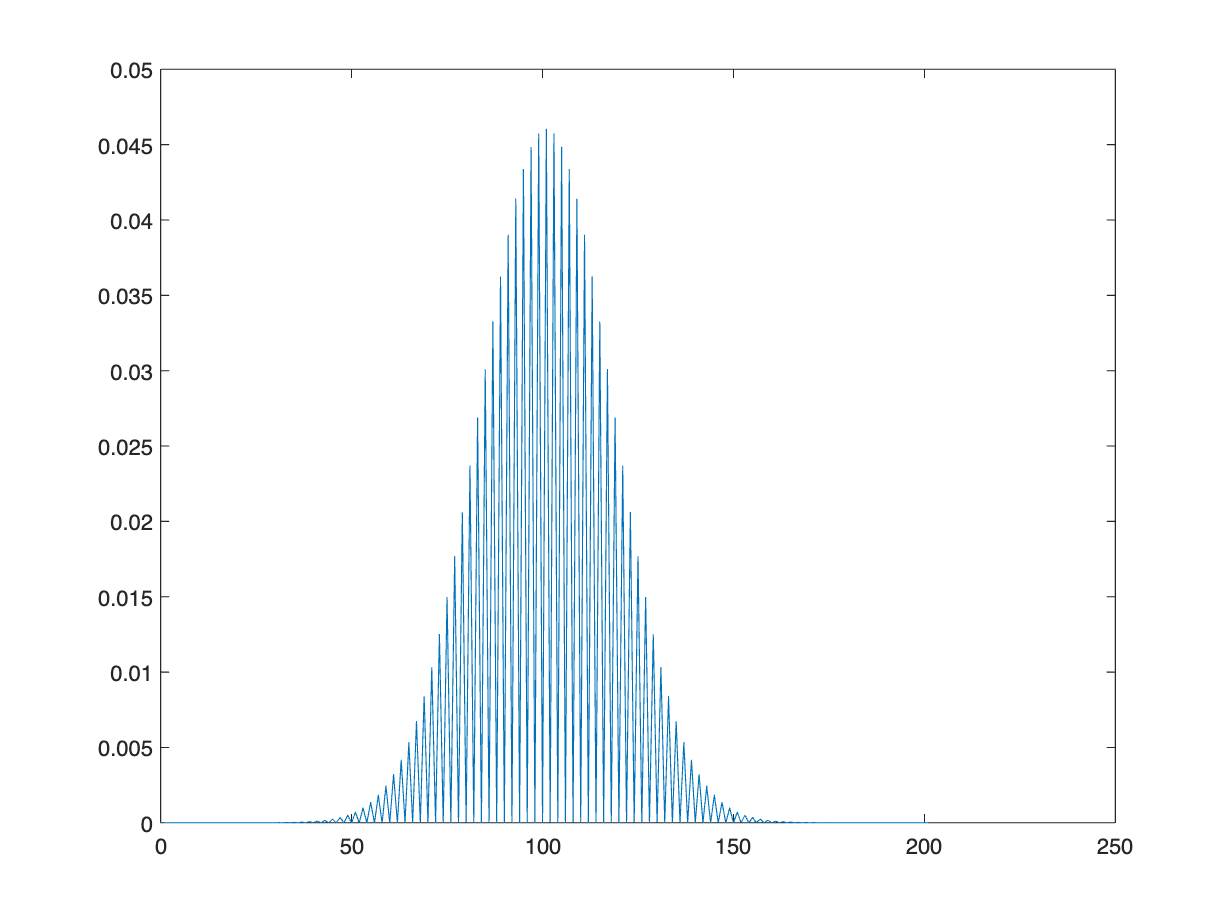

plot(StartNodeP3C*U2P3C^300)

## Problem 3D and 3E

mc = dtmc(U1);

If a markov chain is ergodic, that means that it is irriducible and aperiodic

isergodic(mc)

ans = logical
   1


## Problem 3F

this marko chain has a stationary distribution, and it makes sense that all of the possibilities are equal after a large number of steps.

asymptotics(mc)

ans =    0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099009   0.009900990099009   0.009900990099009   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990099010   0.009900990

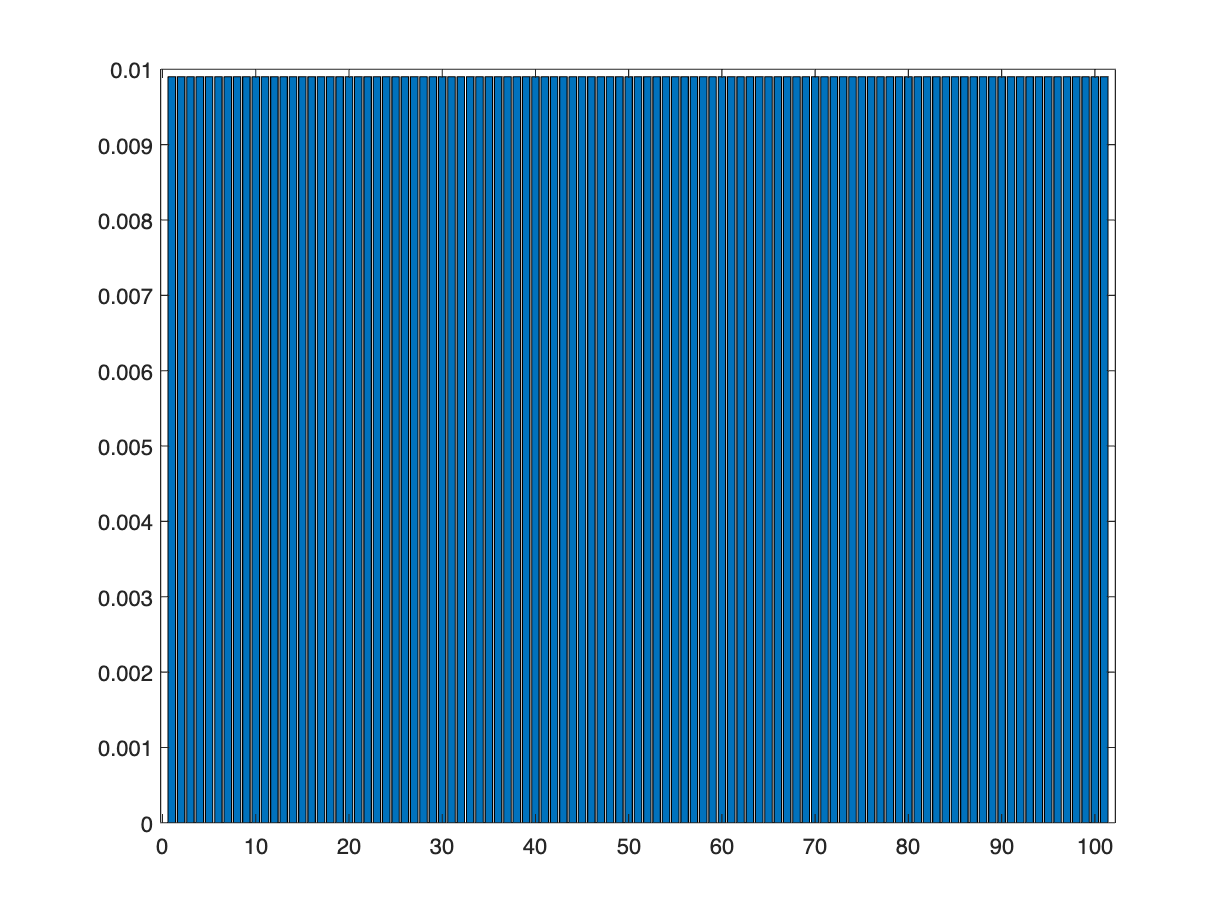

bar(asymptotics(mc));

## Problem 4A

For this problem we use the formula P(n) = (1 − λ/μ)(λ/μ)^n

P4A =    0.079101562500000


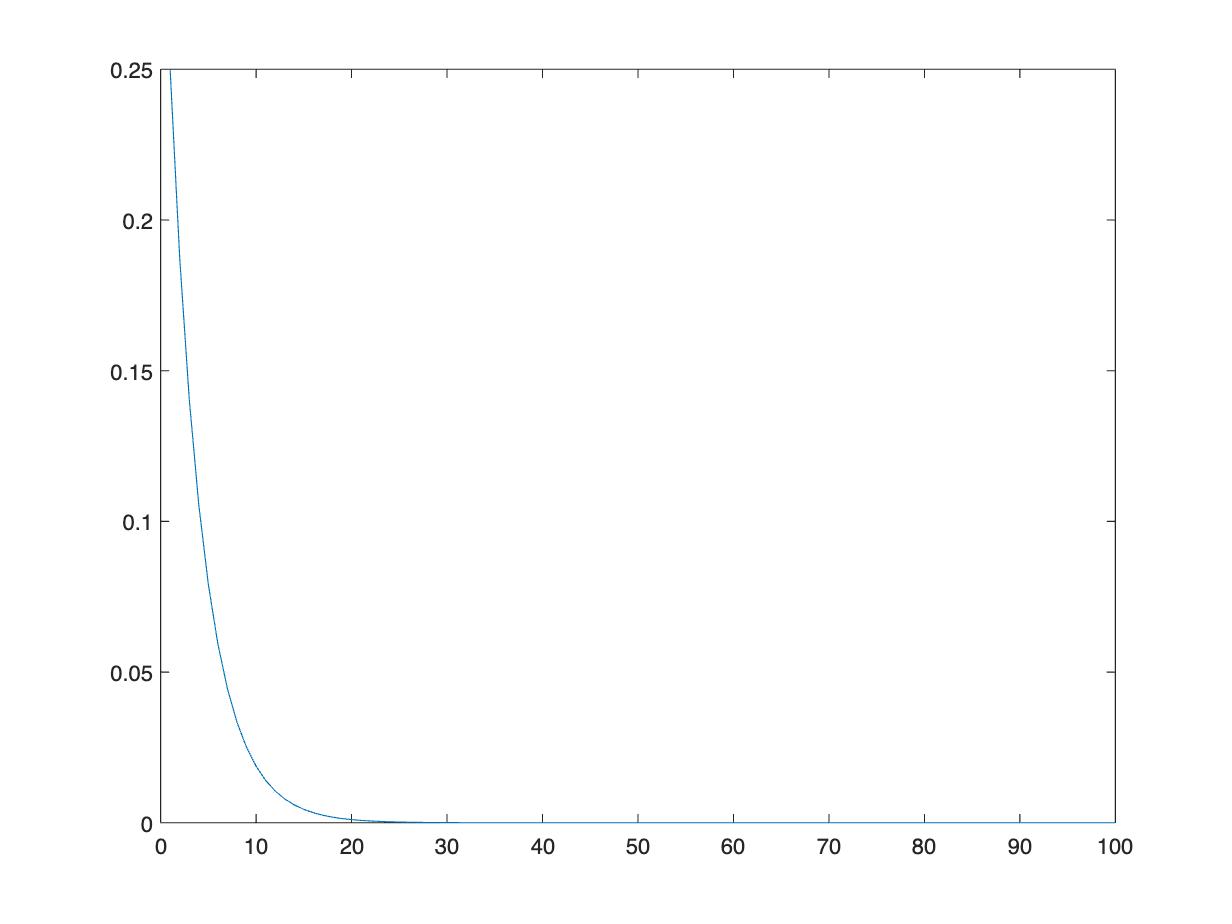

ans =    2.999999999966966


%Average rate of arrival
lambda = 3;
%Average rate of Departure
mu = 4;

P4A = (1-lambda/mu)*(lambda/mu)^4

## Problem 4B

the expected wnumber of people in the queue is μ/(μ-λ).

P4B = lambda/(mu-lambda)

P4B =      3



%another way to do do it with a pdf, come sin handy for part 5
for n = 1:100
    pdf(n) = (1-lambda/mu)*(lambda/mu)^(n-1);
end
plot(pdf);
P4Balt = sum([0:99].*P4Atest)

## Problem 4C

the expected wait time is 1/(μ-λ).

P4C = 1/(mu-lambda)

P4C =      1


## Problem 5A

the markov chain for this will model the number of people in the waiting line

ProbMat = zeros(7);
%defining time
t = 10^-6;


Pa0 = 1-lambda*t; % prob 0 arrivals
Pa1 = lambda*t; % prob 1 arrival
Pd0 = 1 - mu*t; % prob 0 departures
Pd1 = mu*t; % prob 1 arrival


ProbMat(1,1) = Pa0;
ProbMat(1,2) = Pa1;

for i = 2:6
    ProbMat(i,i-1) = Pa0 * Pd1;
    ProbMat(i,i) = Pa0 * Pd0 + Pa1 * Pd1;
    ProbMat(i,i+1) = Pa1 * Pd0;
end

ProbMat(7,1) = Pa0;
ProbMat(7,2) = Pa1;

P5A = ProbMat

ProbMat =    0.999997000000000   0.000003000000000                   0                   0                   0                   0                   0
   0.000003999988000   0.999993000024000   0.000002999988000                   0                   0                   0                   0
                   0   0.000003999988000   0.999993000024000   0.000002999988000                   0                   0                   0
                   0                   0   0.000003999988000   0.999993000024000   0.000002999988000                   0                   0
                   0                   0                   0   0.000003999988000   0.999993000024000   0.000002999988000                   0
                   0                   0                   0                   0   0.000003999988000   0.999993000024000   0.000002999988000
   0.999997000000000   0.000003000000000                   0                   0                   0                   0                   0


## Problem 5B

mc2 = dtmc(ProbMat);
stationary_Distribution = asymptotics(mc2);

%this is the probability of 3 people waiting in line + 1 
%meeting with the president
P5B = stationary_Distribution(4)

P5B =    0.109852683412077


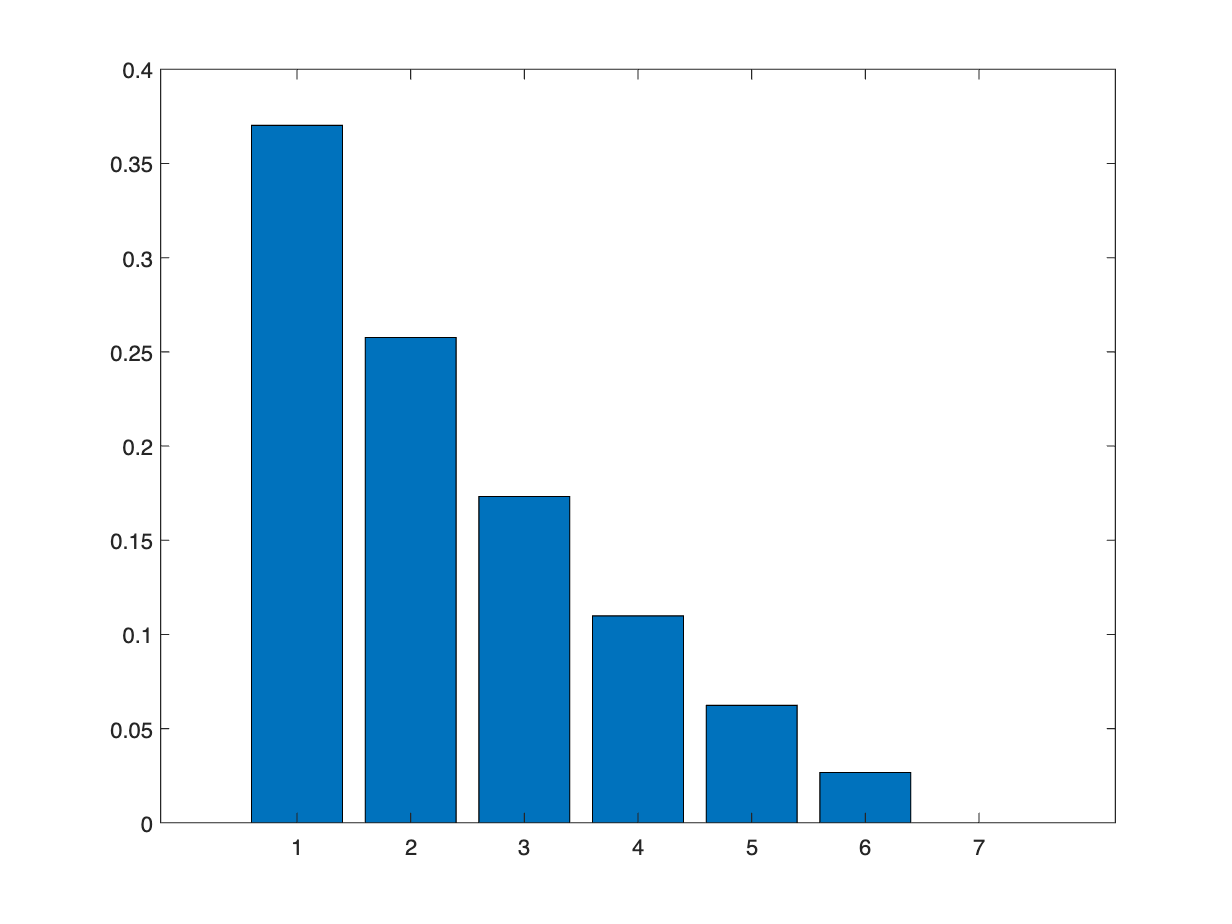

% makes that the probability increases because 6 people is no longer a
% possibility
bar(stationary_Distribution)

## Problem 5C

for expected value, we just sum x*f(x), with f(x) being our stationary distribution

P5C = sum([0:6].*stationary_Distribution)

ans =    1.316583510714090
